# 交差エントロピの凸性

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

x, yをシンボリック変数として定義する(付録A参照)

また，x,yに対する仮定を明記する．

syms x y
assume(x,'real');
assume(x>=0 & x<=1);
assumptions(x)

$$ans = \left[\begin{array}{cc} 0\leq x & x\leq 1 \end{array}\right]$$

assume(y,'real');
assumptions(y)

$$ans = y\in \mathbb{R}$$

Hの定義

H=-(x*log2(y)+(1-x)*log2(1-y))

$$H = \frac{\log\left(-y+1\right)\,\left(x-1\right)}{\log\left(2\right)}-\frac{x\,\log\left(y\right)}{\log\left(2\right)}$$

Hを図示

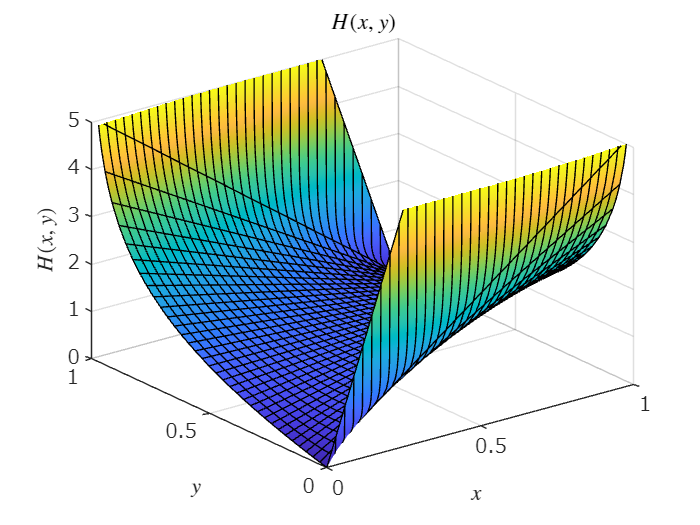

figure;
fsurf(H,[0 1 0 1]);
grid on;set(gca,'fontname','メイリオ','fontsize',12);
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$H(x,y)$','Interpreter','latex');
axis([0 1 0 1 0 5]);clim([0 5]);
title('$H(x,y)$','Interpreter','latex');
exportgraphics(gcf,'fig_H(x,y)_3d.pdf');

xの値を固定してHを図示

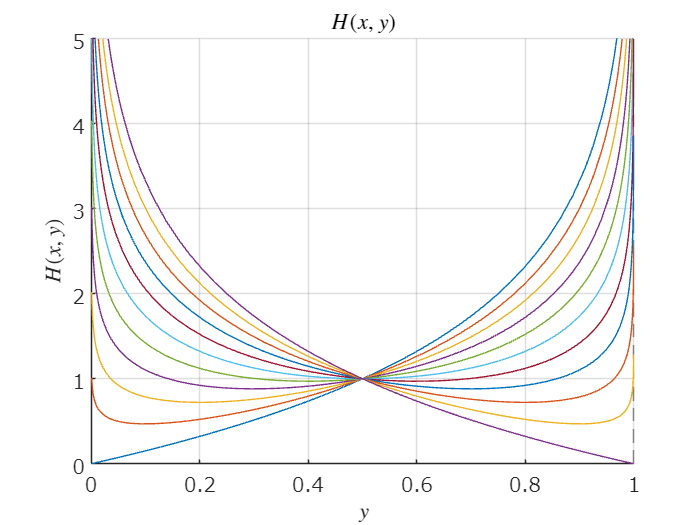

figure;hold on;grid on;set(gca,'fontname','メイリオ','fontsize',12);
axis([0 1 0 5])
for xVal=0:0.1:1
    fplot(subs(H,x,xVal));
end
xlabel('$y$','Interpreter','latex');
ylabel('$H(x,y)$','Interpreter','latex');
title('$H(x,y)$','Interpreter','latex');
exportgraphics(gcf,'fig_H(x,y)_2d.pdf');

simplify(diff(H,y))

$$ans = \frac{x-y}{y\,\log\left(2\right)\,\left(y-1\right)}$$

f=simplify(diff(diff(H,y),y))==0

$$f = \frac{-2\,x\,y+x+y^{2}}{y^{2}\,\log\left(2\right)\,{\left(y-1\right)}^{2}}=0$$

ySol=solve(f,y)

 
ySol =
 
Empty sym: 0-by-1
 



f=simplify(diff(H,y))==0

$$f = \frac{x-y}{y\,\log\left(2\right)\,\left(y-1\right)}=0$$

solve(f,y)

$$ans = x$$